# Unsupervised learning

The dataset "unknown.csv" contains unlabelled examples consisting of two features:

clear all;
data = readtable('unknown.csv');

You suspect the examples can be usefully divided between some number of different classes. Use K-means clustering to estimate an appropriate number of classes.

Marks are available for:

- Visualising the initial data [2 marks]

- Choosing a reasonable range of cluster values to investigate [2 marks]

- Taking sensible steps to decide on the best value within that range [8 marks]

- Visualising the final data with your estimated class labels [4 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

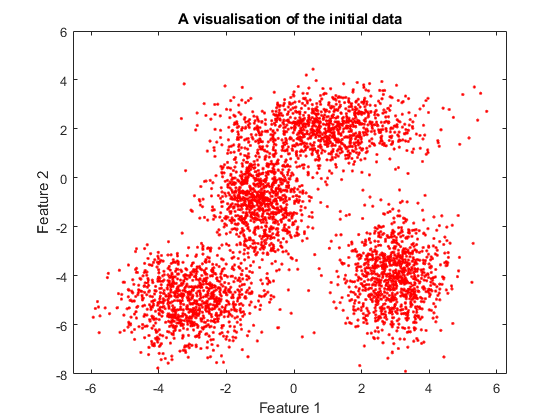

% add as many lines of code as you need below:

% convert the data into a matrix:
data = data{:,:};

% plot the initial data to to visualise it:
gscatter(data(:,1), data(:,2))
title("A visualisation of the initial data");
xlabel("Feature 1");
ylabel("Feature 2");

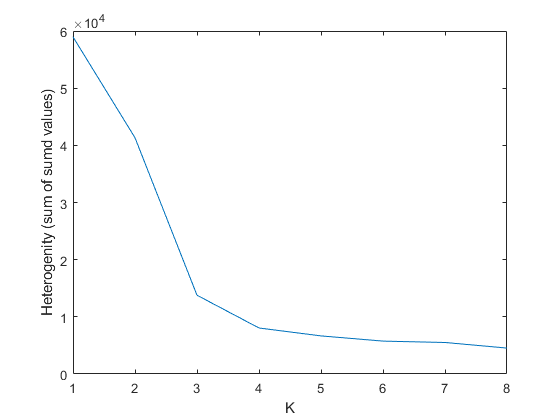


% looking at the visualisation i will choose a range between
% 1-8 clusters.

% set the lowest range value to 1, the highest range value to 8:
low = 1;
high = 8;
heterogenity = [];

% perform k means on all the values of K in the range:
for k=low:high
    % perform kmeans and return sumd to calculate the sum of the distances
    % between all the points in the cluster and the cluster centre:
    [~, ~, sumd] = kmeans(data, k, 'Start', 'uniform');
    % calculate the sum of the sumd values and add to array:
    heterogenity(end+1) = sum(sumd);
end

% plot the K values againts the sum of the sumd values:
plot(low:high, heterogenity)
xlabel("K")
ylabel("Heterogenity (sum of sumd values)")

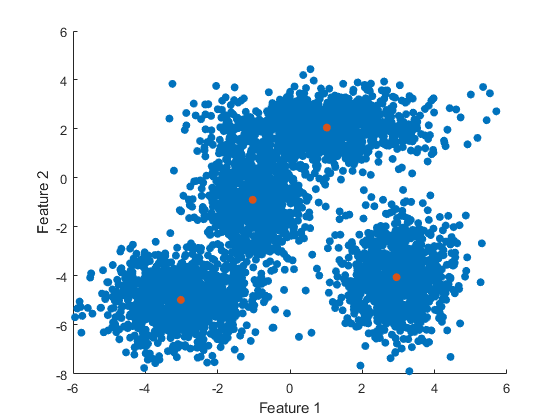


% looking at where the elbow plot bends, i will choose 4 as the
% optimal number of clusters.
figure 
% plot the original data:
scatter(data(:,1), data(:,2), 'filled')
hold on
% perform kmeans with my chosen value of K:
[memberships, clusters] = kmeans(data, 4, 'Start', 'uniform', 'MaxIter', 50);
% plot the values of the center of each clusters:
scatter(clusters(:,1), clusters(:,2), 'filled')
xlabel("Feature 1");
ylabel("Feature 2");
hold off